# Ejercicio 1

## a)

### Construcción del Algorit:

function H = Hessenberg(A)

    [m, ~] = size(A); %Obtener el número de filas
    H = A; % Hacer la matriz de H (Hessenberg) igual a A para no modifica A

    for k = 1:m-2
        x = H(k+1:m, k);
  
        e1 = zeros(length(x), 1);
        e1(1) = 1;

        
        vk = sign(x(1)) * norm(x) * e1 + x;
        vk = vk / norm(vk); % Normalizar vk

        % Actualizar la submatriz H(k+1:m, k:m)
        H(k+1:m, k:m) = H(k+1:m, k:m) - 2 * vk * (vk' * H(k+1:m, k:m));
        
        % Actualizar las filas H(1:m, k+1:m)
        H(1:m, k+1:m) = H(1:m, k+1:m) - 2 * (H(1:m, k+1:m) * vk) * vk';
    end
end

## b)

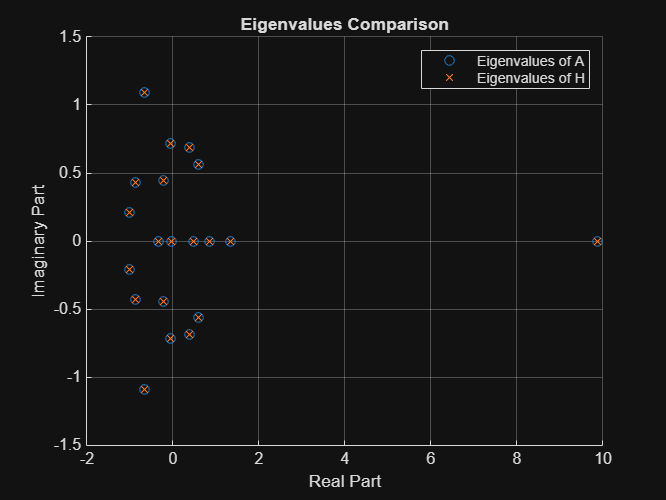

m = 20;
A = rand(m);

% Matriz de Hessenberg Aleatoria
H = Hessenberg(A);

% Calcular los valores propios de matriz A y H
eig_A = eig(A); 
eig_H = eig(H); 

% Visualizar los valores propios
figure;
scatter(real(eig_A), imag(eig_A), 'o', 'DisplayName', 'Eigenvalues of A');
hold on;
scatter(real(eig_H), imag(eig_H), 'x', 'DisplayName', 'Eigenvalues of H');
xlabel('Real Part');
ylabel('Imaginary Part');
title('Eigenvalues Comparison');
legend;
grid on;


% Ver error entre los valores propios
diff = norm(sort(eig_A) - sort(eig_H)); % Norma de las diferencias
fprintf('La diferencia entre los valores propios es: %.5e\n', diff);

La diferencia entre los valores propios es: 1.32059e-14


# Ejercicio 2

### Inciso a)

function [secuencia_sturm, concordancia_signo] = calcular_secuencia_sturm(a, b, theta)
m = length(a); % Tamaño de la matriz
p_prev = 1; % Polinomio P_0(theta)
p_curr = a(1) - theta; % Polinomio P_1(theta)
secuencia_sturm = zeros(1, m);
secuencia_sturm(1) = p_prev;
secuencia_sturm(2) = p_curr;

for i = 2:m-1
    % Recurrencia de Sturm
    p_sig = (a(i) - theta) * p_curr - b(i)^2 * p_prev;
    secuencia_sturm(i + 1) = p_sig;
    p_prev = p_curr;
    p_curr = p_sig;
end

% Contar concordancia de signo
concordancia_signo = sum(diff(sign(secuencia_sturm)) ~= 0);
end

### Inciso b)

function menor_valor_propio = calcular_menor_valor_propio(a, b, tol)

% Intervalo inicial (Teorema de Gershgorin)
lim_inf = 2;
lim_sup = 6;

% Aplicar método de bisección para encontrar el menor valor propio
while (lim_sup - lim_inf) > tol
    mid = (lim_inf + lim_sup) / 2;
    [~, concordancia_signo] = calcular_secuencia_sturm(a, b, mid);
    if concordancia_signo < length(a)
        lim_sup = mid;
    else
        lim_inf = mid;
    end
end
menor_valor_propio = (lim_inf + lim_sup) / 2;
end

function mayor_valor_propio = calcular_mayor_valor_propio(a, b, tol)

% Intervalo inicial (Teorema de Gershgorin)
lim_inf = 2;
lim_sup = 6;

% Aplicar método de bisección para encontrar el mayor valor propio
while (lim_sup - lim_inf) > tol
    mid = (lim_inf + lim_sup) / 2;
    [~, concordancia_signo] = calcular_secuencia_sturm(a, b, mid);
    if concordancia_signo > 0
        lim_inf = mid;
    else
        lim_sup = mid;
    end
end
mayor_valor_propio = (lim_inf + lim_sup) / 2;
end

% Tamaño de la diagonal 
m = 10^6;
a = 4 * ones(m, 1); % Diagonal
b = -1 * ones(m-1, 1); % Sub/Superdiagonal
tol = 1e-6;

menor_valor_propio = calcular_menor_valor_propio(a, b, tol);
mayor_valor_propio = calcular_mayor_valor_propio(a, b, tol);

disp(['Valor propio mínimo: ', num2str(menor_valor_propio)]);

Valor propio mínimo: 2


disp(['Valor propio máximo: ', num2str(mayor_valor_propio)]);

Valor propio máximo: 6


### Inciso c)

% Crear índices para la matriz dispersa
i = [1:m, 2:m, 1:m-1];       
j = [1:m, 1:m-1, 2:m];       
s = [a; b; b];  

% Crear la matriz dispersa
T = sparse(i, j, s, m, m);  

% Aplicar comandos 
eigs(T, 1, 'LM');

eigs(T, 1, 'SM');

Los comandos para calcular un valor propio de mayor magnitud y un valor propio de menor magnitud no convergieron, esto se debe a las grandes dimensiones de la matriz T, cuyo tamaño es de 10^6x10^6.